# **CA#1 **

## **Name: Sogol Goodarzi **

## **SID: 810198467**

# **Part 2**

## 2.1)

### Choosing 1 sec of sound :

[data,Fs1]=audioread('sound.mp3');
x=data(1:1*Fs1);
sound(x,Fs1);

## 2.2)

### Value and Phase of x[n] :

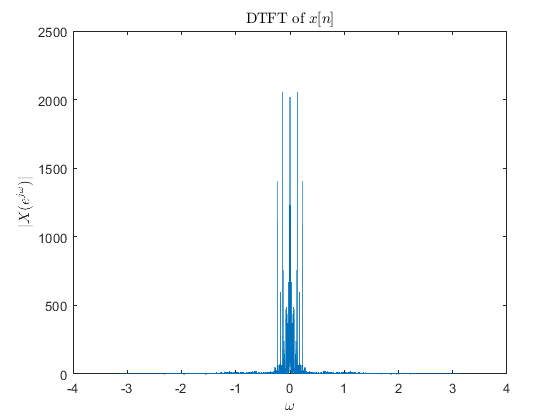

n=0:1:1*Fs1-1;
w=linspace(-pi,pi,length(x));
X=DTFT(x,n,w);
plot(w,abs(X));
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$|X(e^{j\omega})|$','Interpreter','latex')
title ('DTFT of $x[n]$','Interpreter','latex')

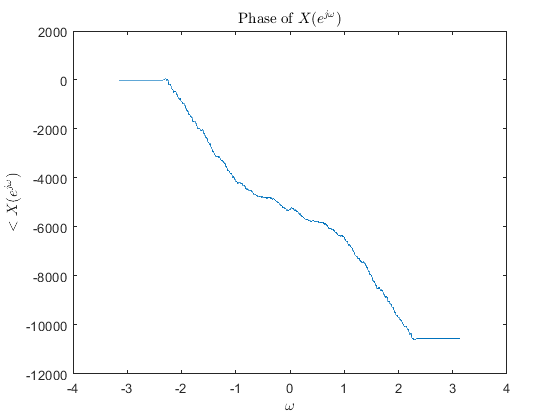

plot(w,phase(X));
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$<X(e^{j\omega})$','Interpreter','latex')
title ('Phase of $X(e^{j\omega})$','Interpreter','latex')

### 2.4)

M=2;   L=3;
xe=Expander(x,L);     %% Expander block
ne=(L*n(1)):1:(L*n(length(n)));
Xe=DTFT(xe,ne,w);     %% DTFT of xe[n]

Matrix dimensions must agree.

Error in CA1_part2>DTFT (line 36)
    FT(m)=sum(x.*exp(-1i*w(m)*n));

ye=Interpolate(xe,ne,3,L,Fs1);  %% Interpolation block (spline)
xd=Compressor(ye,M);  %% Compressor block
% nd=ne()

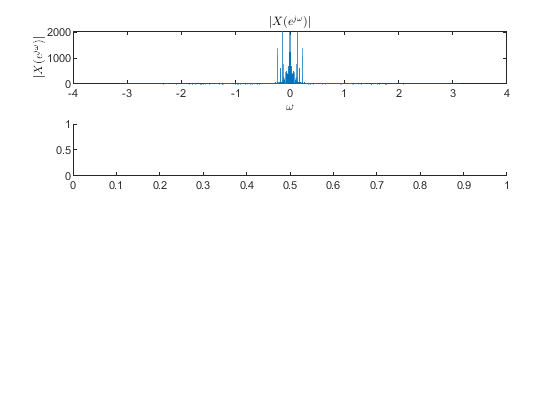

subplot(4,1,1);
plot(w,abs(X));
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$|X(e^{j\omega})|$','Interpreter','latex')
title ('$|X(e^{j\omega})|$','Interpreter','latex')
subplot(4,1,2);

plot(w,abs(Xe));

Undefined function or variable 'Xe'.

xlabel ('$\omega$','Interpreter','latex')
ylabel ('$|X_e(e^{j\omega})|$','Interpreter','latex')
title ('$|X_e(e^{j\omega})|$','Interpreter','latex')
subplot(4,1,3);


# **Functions **

## DTFT:

function [FT] = DTFT(x,n,w)
for m=1:length(w)
    FT(m)=sum(x.*exp(-1i*w(m)*n));
end
end

## Compressor

function [y]=Compressor(x,M)
y=x(1:M:length(x));
end

## Expander

function [y]=Expander(x,L)
y=zeros(1,length(x)*L);
y(1:L:length(y))=x;
end

## Interpolate

function [y]=Interpolate(x,n,mode,L,fs)
n_=n(1:L:length(n))/L;  %% indexes before Expansion
xs=x(1:L:length(x));    %% values of signal before Expansion
t=n/(fs*L);
if mode==1    %% Ideal interpolation
    y=xs*sinc(ones(length(n_),1)*n/L-n_'*ones(1,length(n)));
end
if mode==2    %% Linear interpoltion
    for i=-L:L
        h_lin(i+L+1)=1-abs(i)/L;
    end
    y=conv(x,h_lin);
    y=y(L:length(y)-L-1);
end
if mode==3   %% spline interpolation
    y=spline(n_/fs,xs,t);
end
end